# Projeto - META 1

## 1: Criação da tabela com informações extraídas dos nomes dos arquivos

% Define o caminho para os arquivos e obtém a lista de arquivos
caminho = "data/36";
arquivos = dir(caminho);
% Filtra para manter apenas arquivos (não diretórios)
arquivosFiltrados = arquivos([arquivos.isdir] == 0);
% Converte a estrutura em tabela
tabela = struct2table(arquivosFiltrados);

% Número total de arquivos
nArquivos = height(tabela);

% Inicializa vetores para armazenar os dígitos, participantes e repetições extraídas dos nomes
digitos = zeros(nArquivos, 1);
participantes = zeros(nArquivos, 1);
repeticoes = zeros(nArquivos, 1);

% Loop para processar cada nome de arquivo
for i = 1:nArquivos
    nomeArquivo = tabela.name{i};
    % Remove a extensão do arquivo (por exemplo, '.wav')
    [~, nomeSemExt, ~] = fileparts(nomeArquivo);
    % Separa os componentes do nome utilizando o underline como delimitador
    partes = split(nomeSemExt, '_');
    
    if numel(partes) >= 3
        % Converte os componentes para número:
        % Primeiro elemento = dígito, segundo = participante, terceiro = repetição
        digitos(i) = str2double(partes{1});
        participantes(i) = str2double(partes{2});
        repeticoes(i) = str2double(partes{3});
    else
        % Emite um aviso se o formato do nome for inesperado
        warning('Formato de nome inesperado: %s', nomeArquivo);
        digitos(i) = NaN;
        participantes(i) = NaN;
        repeticoes(i) = NaN;
    end
end

% Cria uma nova tabela com os dados extraídos e informações de diretório e nome do arquivo
novaTabela = table(tabela.folder, tabela.name, participantes, digitos, repeticoes, ...
    'VariableNames', {'Diretorio_Audio', 'Nome_Arquivo', 'Participante', 'Digito', 'Repeticoes'})

novaTabela = 500×5 table
                            Diretorio_Audio                             Nome_Arquivo      Participante    Digito    Repeticoes
    _______________________________________________________________    _______________    ____________    ______    __________

    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_0.wav' }         36           0            0    
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_1.wav' }         36           0            1    
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_10.wav'}         36           0           10    
    {'/Users/franciscosantos/Documents/GitHub/Projeto_ATD/data/36'}    {'0_36_11.wav'}         36           0           11    
    {'/Users/franciscosantos/Documents/Git

## 2: Carregamento dos arquivos de áudio e criação de uma tabela com os sinais

% Obtém a lista de arquivos com extensão '.wav'
arquivos = dir(fullfile(caminho, "*.wav"));
nomes = {arquivos.name}';
% Inicializa vetores para taxas de amostragem e sinais
taxasAmostragem = zeros(length(arquivos), 1);
sinais = cell(length(arquivos), 1);

% Loop para ler cada arquivo de áudio
for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name);
    [sinal, fs] = audioread(caminhoArquivo);
    taxasAmostragem(i) = fs;
    sinais{i} = sinal;
end

% Cria uma tabela com os nomes dos arquivos, taxas de amostragem e sinais
tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38637×1 double}
    {'0_36_1.wav' }         48000         {36217×1 double}
    {'0_36_10.wav'}         48000         {43932×1 double}
    {'0_36_11.wav'}         48000         {35604×1 double}
    {'0_36_12.wav'}         48000         {34260×1 double}
    {'0_36_13.wav'}         48000         {35326×1 double}
    {'0_36_14.wav'}         48000         {40242×1 double}
    {'0_36_15.wav'}         48000         {38791×1 double}
    {'0_36_16.wav'}         48000         {41981×1 double}
    {'0_36_17.wav'}         48000         {40212×1 double}
    {'0_36_18.wav'}         48000         {39723×1 double}
    {'0_36_19.wav'}         48000         {39483×1 double}
    {'0_36_2.wav' }         48000         {42

## 3: Extração de dígitos e repetições e criação de gráficos dos sinais para uma repetição específica

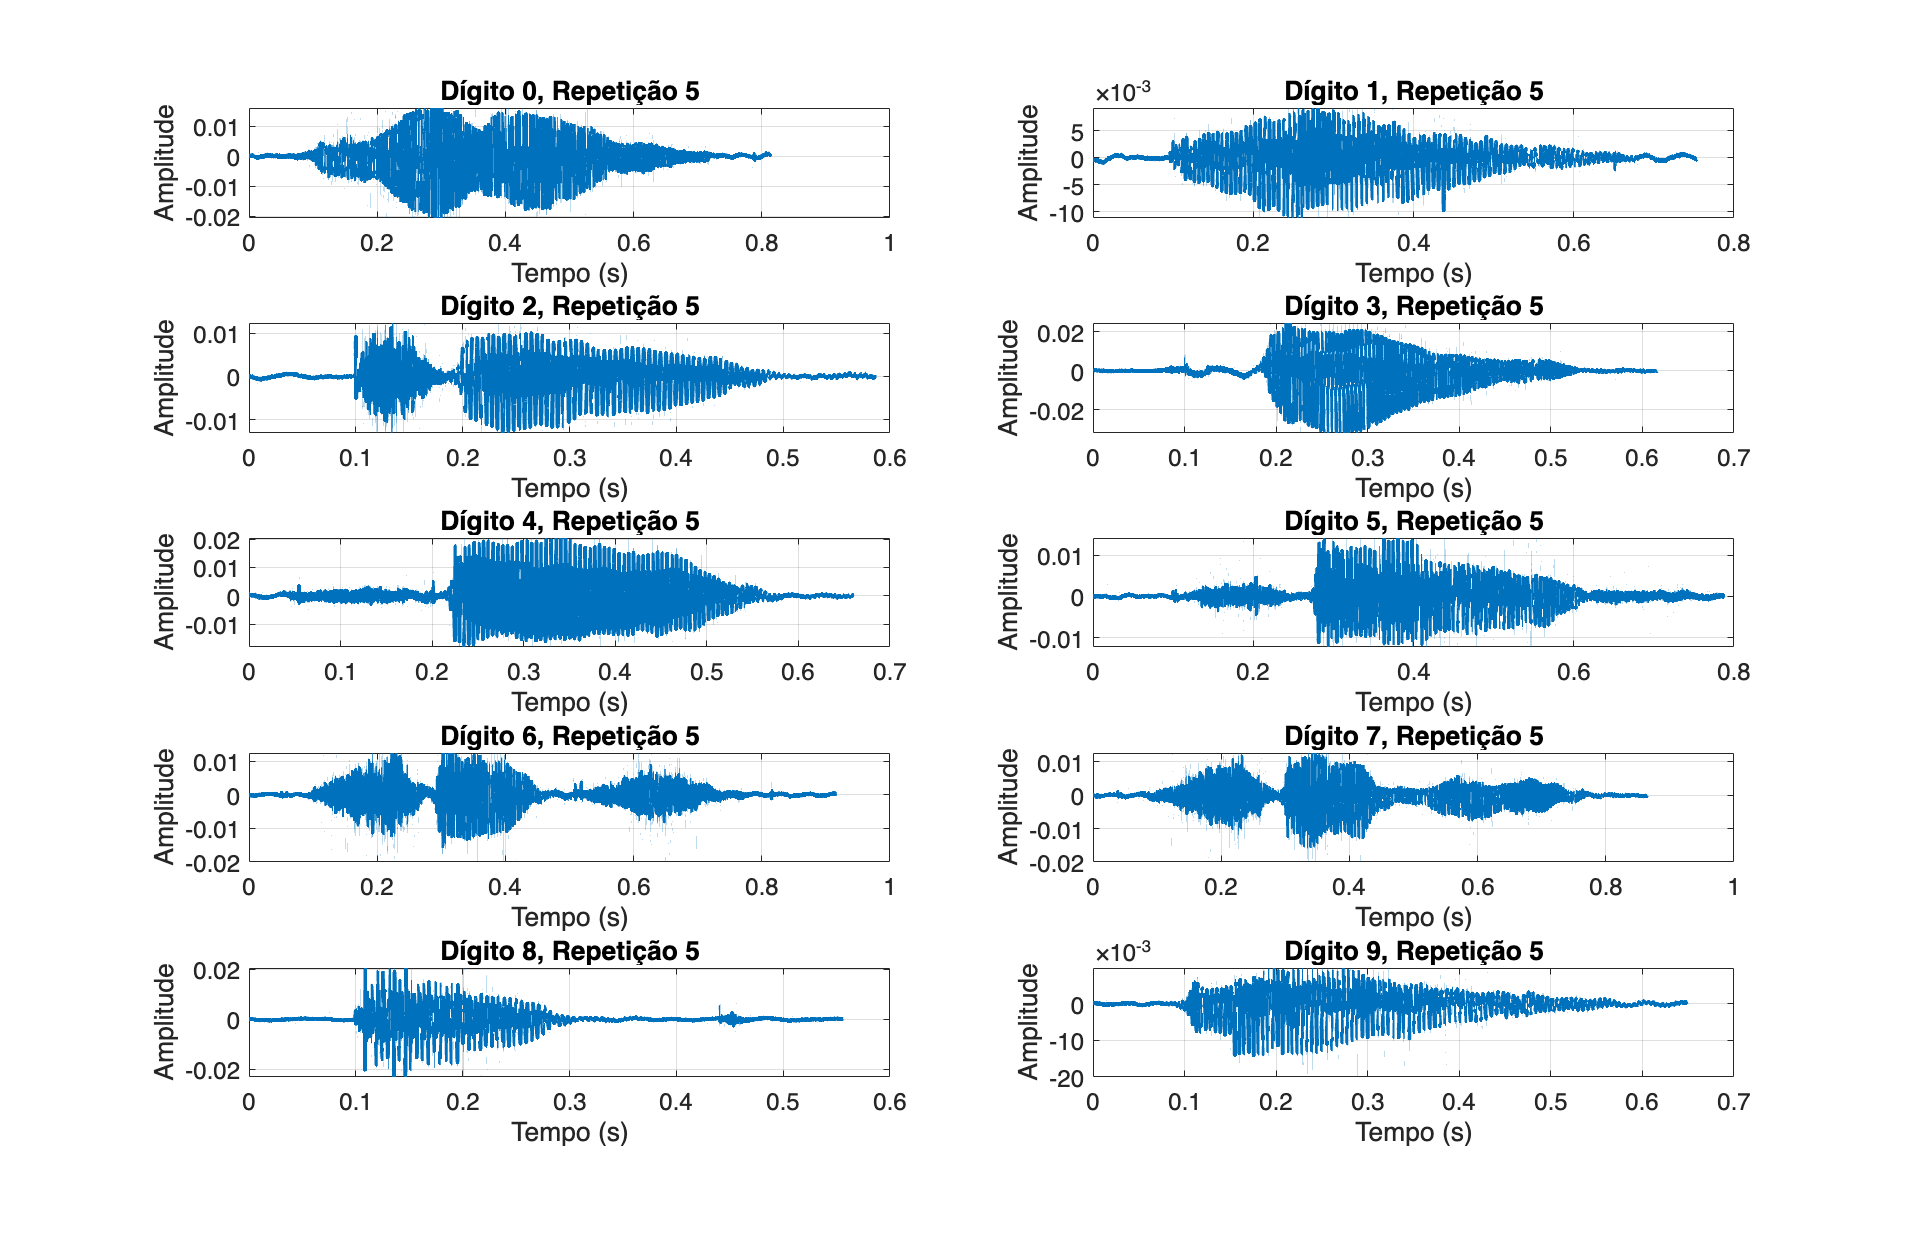

% Inicializa vetores para armazenar dígitos e repetições
nArquivos = height(tabArquivos);
digitos = zeros(nArquivos,1);
repeticoes = zeros(nArquivos,1);

% Loop para extrair dígito e repetição a partir do nome do arquivo
for i = 1:nArquivos
   [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
   partes = split(nomeSemExt, '_');
   % Primeiro número corresponde ao dígito
   digitos(i) = str2double(partes{1});
   % Terceiro número corresponde à repetição
   repeticoes(i) = str2double(partes{3});
end

% Adiciona as novas colunas à tabela
tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtra apenas os arquivos da repetição desejada (por exemplo, repetição 5)
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);

% Obtém os dígitos disponíveis nessa repetição
digitosUnicos = unique(T_filtro.Digito);
numDigitos = numel(digitosUnicos);

if numDigitos < 1
    error('Nenhum dígito disponível na repetição %d.', repEscolhida);
end

% Define a quantidade de subplots (2 gráficos por linha)
numColunas = 2;
numLinhas = ceil(numDigitos / numColunas);

% Cria uma nova figura para os gráficos
figure('Name', sprintf('Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

% Loop para fazer os gráficos de cada sinal referente a um dígito único
for i = 1:numDigitos
    digitoAtual = digitosUnicos(i);
    
    % Seleciona o primeiro arquivo para o dígito atual
    T_atual = T_filtro(T_filtro.Digito == digitoAtual, :);
    
    sinal = T_atual.Sinal{1};
    fs = T_atual.Taxa_Amostragem(1);
    
    % Cria um vetor de tempo para o eixo x
    t = (0:length(sinal)-1) / fs;
    
    % Criação do subplot e plot do sinal
    subplot(numLinhas, numColunas, i)
    plot(t, sinal, 'LineWidth', 2)
    title(sprintf('Dígito %d, Repetição %d', digitoAtual, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    set(gca, 'FontSize', 12)
    grid on
end

## 4: Carregamento dos arquivos de áudio com processamento: remoção de silêncio, normalização e ajuste de duração

% Obtém a lista de arquivos '.wav'
arquivos = dir(fullfile(caminho, "*.wav"));
nomes = {arquivos.name}';
taxasAmostragem = zeros(length(arquivos), 1);
sinais = cell(length(arquivos), 1);

% Loop para ler e processar cada arquivo de áudio
for i = 1:length(arquivos)
    caminhoArquivo = fullfile(arquivos(i).folder, arquivos(i).name);
    [sinal, fs] = audioread(caminhoArquivo);
    
    % Remoção de silêncio inicial usando um limiar (threshold)
    limiar = 0.02;
    idx = find(abs(sinal) > limiar, 1, 'first');
    if ~isempty(idx)
        sinal = sinal(idx:end);
    end
    
    % Normaliza o sinal para o intervalo [-1, 1]
    if max(sinal) ~= min(sinal)
        sinal = 2 * (sinal - min(sinal)) / (max(sinal) - min(sinal)) - 1;
    end
    
    % Ajusta a duração do sinal para 0.8 segundos, completando com zeros se necessário
    duracao_alvo = 0.8;
    num_amostras_alvo = round(duracao_alvo * fs);
    if length(sinal) < num_amostras_alvo
        sinal = [sinal; zeros(num_amostras_alvo - length(sinal), 1)];
    elseif length(sinal) > num_amostras_alvo
        sinal = sinal(1:num_amostras_alvo);
    end
    
    taxasAmostragem(i) = fs;
    sinais{i} = sinal;
end

% Cria uma nova tabela com os sinais processados
tabArquivos = table(nomes, taxasAmostragem, sinais, ...
    'VariableNames', {'Nome_Arquivo', 'Taxa_Amostragem', 'Sinal'})

tabArquivos = 500×3 table
     Nome_Arquivo      Taxa_Amostragem         Sinal      
    _______________    _______________    ________________

    {'0_36_0.wav' }         48000         {38400×1 double}
    {'0_36_1.wav' }         48000         {38400×1 double}
    {'0_36_10.wav'}         48000         {38400×1 double}
    {'0_36_11.wav'}         48000         {38400×1 double}
    {'0_36_12.wav'}         48000         {38400×1 double}
    {'0_36_13.wav'}         48000         {38400×1 double}
    {'0_36_14.wav'}         48000         {38400×1 double}
    {'0_36_15.wav'}         48000         {38400×1 double}
    {'0_36_16.wav'}         48000         {38400×1 double}
    {'0_36_17.wav'}         48000         {38400×1 double}
    {'0_36_18.wav'}         48000         {38400×1 double}
    {'0_36_19.wav'}         48000         {38400×1 double}
    {'0_36_2.wav' }         48000         {38

## 5: Extração do dígito e repetição dos nomes dos arquivos e filtragem por repetição

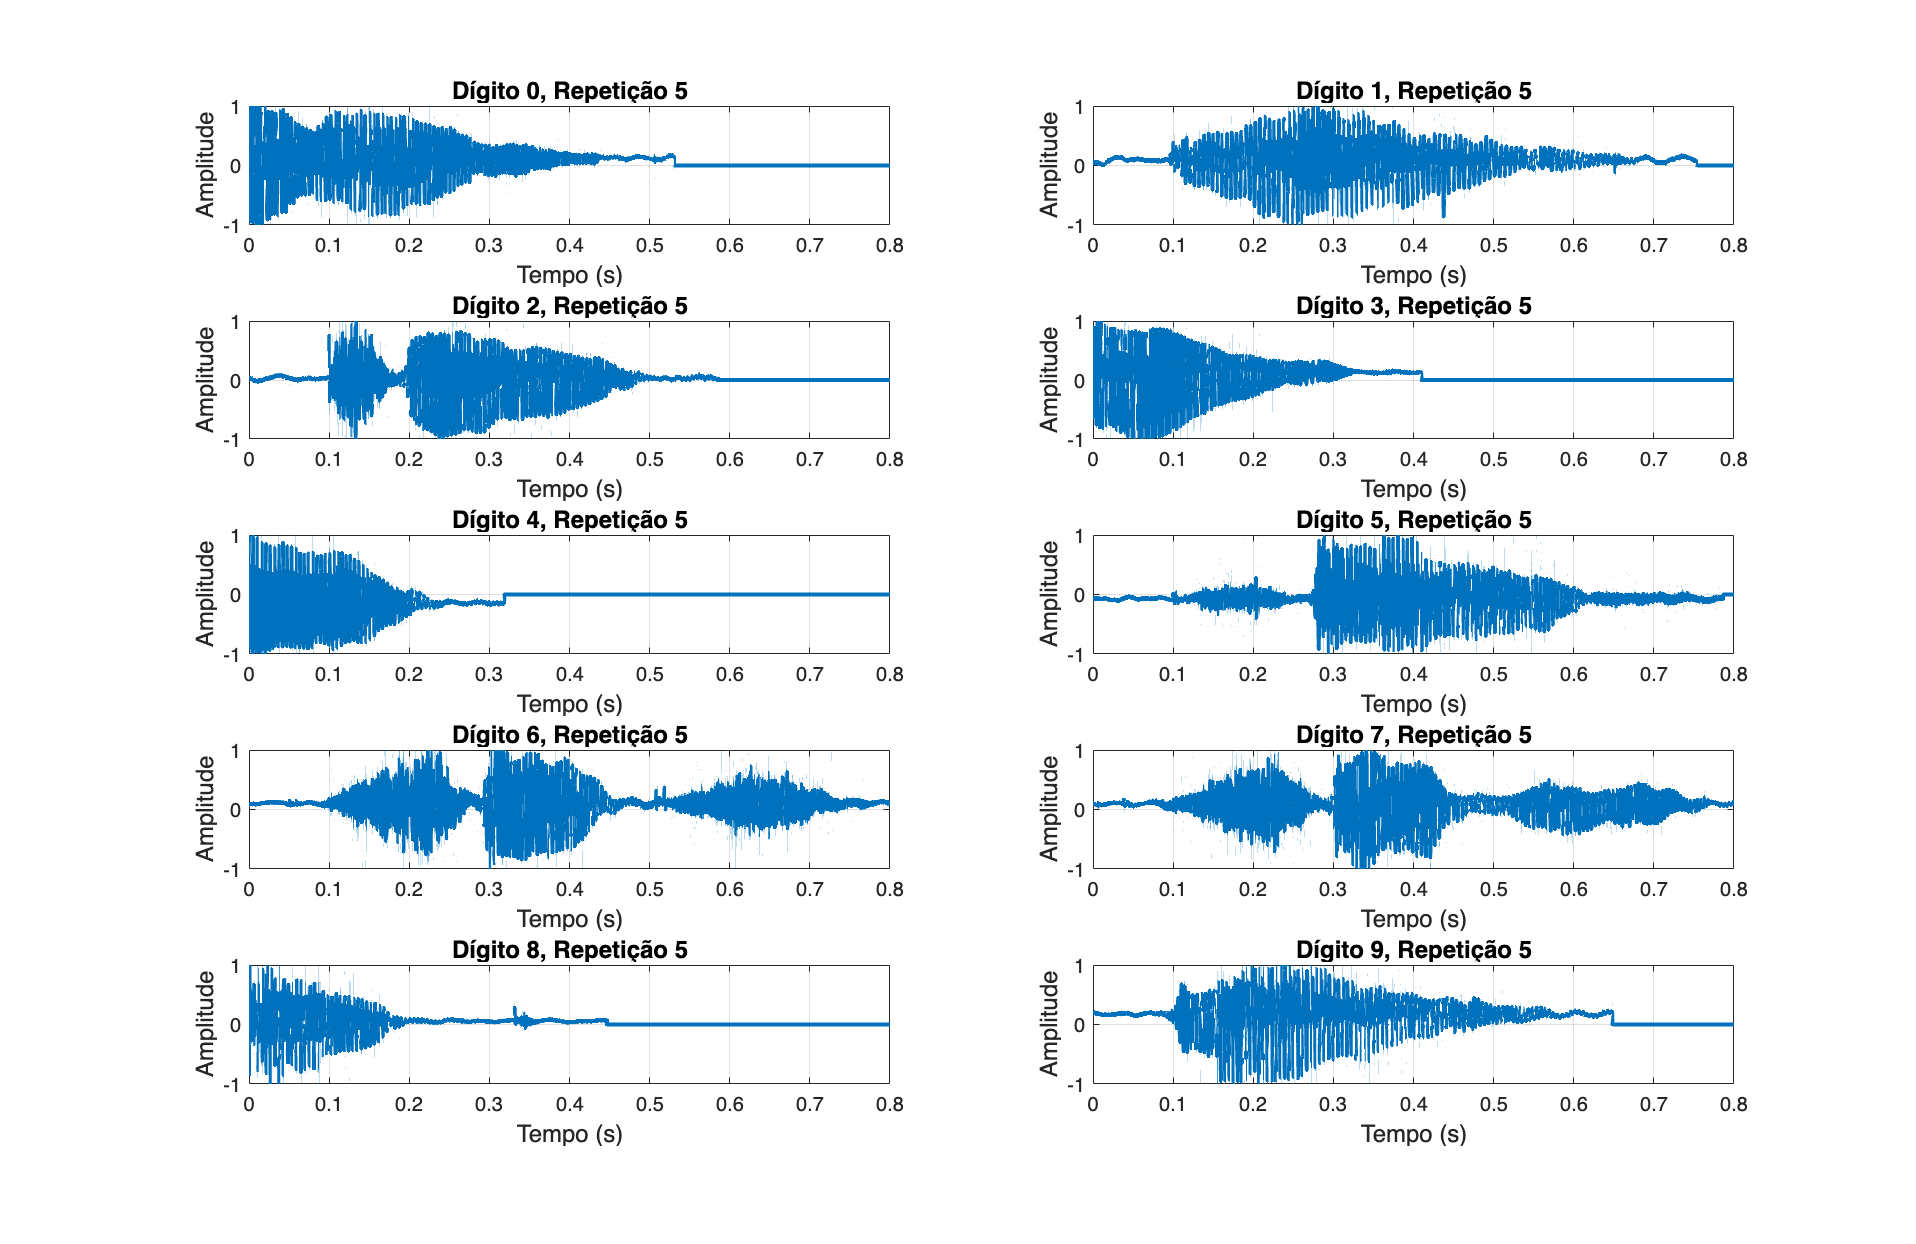

% Inicializa vetores para dígitos e repetições
nArquivos = height(tabArquivos);
digitos = zeros(nArquivos,1);
repeticoes = zeros(nArquivos,1);

% Loop para extrair informações dos nomes dos arquivos
for i = 1:nArquivos
    [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    partes = split(nomeSemExt, '_');
    if numel(partes) >= 3
        digitos(i) = str2double(partes{1});
        repeticoes(i) = str2double(partes{3});
    else
        warning('Formato inesperado: %s', tabArquivos.Nome_Arquivo{i});
        digitos(i) = NaN;
        repeticoes(i) = NaN;
    end
end

% Adiciona as colunas extraídas à tabela
tabArquivos.Digito = digitos;
tabArquivos.Repeticao = repeticoes;

% Filtra os arquivos que correspondem à repetição 5
repEscolhida = 5;
T_filtro = tabArquivos(tabArquivos.Repeticao == repEscolhida, :);
if isempty(T_filtro)
    error('Nenhum arquivo encontrado para a repetição %d.', repEscolhida);
end

% Obtém os dígitos únicos para os gráficos
digitosUnicos = unique(T_filtro.Digito);
numDigitos = numel(digitosUnicos);
numColunas = 2;
numLinhas = ceil(numDigitos / numColunas);

% Cria uma nova figura para exibir os sinais
figure('Name', sprintf('Sinais - Repetição %d', repEscolhida), 'NumberTitle','off', ...
       'Units','normalized', 'OuterPosition',[0 0 1 1]);

% Loop para fazer os gráficos de cada sinal por dígito
for i = 1:numDigitos
    digitoAtual = digitosUnicos(i);
    T_atual = T_filtro(T_filtro.Digito == digitoAtual, :);
    
    sinal = T_atual.Sinal{1};
    fs = T_atual.Taxa_Amostragem(1);
    t = (0:length(sinal)-1) / fs;
    
    subplot(numLinhas, numColunas, i)
    plot(t, sinal, 'LineWidth', 2)
    title(sprintf('Dígito %d, Repetição %d', digitoAtual, repEscolhida), 'FontSize', 12)
    xlabel('Tempo (s)', 'FontSize', 12)
    ylabel('Amplitude', 'FontSize', 12)
    grid on;
end

## 6: (Resolução realizada no relatório)

## 7: Cálculo das características temporais e criação da tabela final

% Extrai metadados dos nomes dos arquivos: participante, dígito e repetição
nArquivos = height(tabArquivos);
participante = zeros(nArquivos,1);
digito = zeros(nArquivos,1);
repeticao = zeros(nArquivos,1);

for i = 1:nArquivos
    [~, nomeSemExt, ~] = fileparts(tabArquivos.Nome_Arquivo{i});
    partes = split(nomeSemExt, '_');
    if numel(partes) >= 3
        digito(i)       = str2double(partes{1});
        participante(i) = str2double(partes{2});
        repeticao(i)    = str2double(partes{3});
    else
        warning('Formato inesperado: %s', tabArquivos.Nome_Arquivo{i});
        digito(i) = NaN;
        participante(i) = NaN;
        repeticao(i) = NaN;
    end
end

% Adiciona as colunas extraídas à tabela
tabArquivos.Participante = participante;
tabArquivos.Digito       = digito;
tabArquivos.Repeticao    = repeticao;

% Inicializa vetores para as características temporais
EnergiaTotal           = zeros(nArquivos,1);
EnergiaPrimeiraMetade  = zeros(nArquivos,1);
EnergiaSegundaMetade   = zeros(nArquivos,1);
DesvioPadraoAmplitude  = zeros(nArquivos,1);
RMS                    = zeros(nArquivos,1);
MediaAmplitude         = zeros(nArquivos,1);
fatorCrest             = zeros(nArquivos,1);
taxaCruzamento         = zeros(nArquivos,1);

% Loop para calcular as características de cada sinal
for i = 1:nArquivos
    s = tabArquivos.Sinal{i};
    
    % Calcula a energia total do sinal
    EnergiaTotal(i) = sum(s.^2);
    % Divide o sinal ao meio e calcula a energia de cada metade
    halfPoint = floor(length(s)/2);
    EnergiaPrimeiraMetade(i) = sum(s(1:halfPoint).^2);
    EnergiaSegundaMetade(i)  = sum(s(halfPoint+1:end).^2);
    
    % Calcula o desvio padrão da amplitude
    DesvioPadraoAmplitude(i) = std(s);
    
    % Calcula o valor RMS e a média da amplitude
    RMS(i) = sqrt(mean(s.^2));
    MediaAmplitude(i) = mean(s);
    
    % Calcula o fator de Crest: razão entre o valor máximo absoluto e o RMS
    fatorCrest(i) = max(abs(s)) / RMS(i);
    
    % Calcula a taxa de cruzamento por zero do sinal
    numZeroCross = sum(abs(diff(sign(s))))/2;
    taxaCruzamento(i) = numZeroCross / length(s);
end

% Cria a tabela final com todas as características calculadas (exceto o sinal)
tabelaFinal = table(tabArquivos.Nome_Arquivo, tabArquivos.Participante, tabArquivos.Digito, tabArquivos.Repeticao, ...
    tabArquivos.Taxa_Amostragem, EnergiaTotal, EnergiaPrimeiraMetade, EnergiaSegundaMetade, ...
    DesvioPadraoAmplitude, RMS, MediaAmplitude, fatorCrest, taxaCruzamento, ...
    'VariableNames', {'Nome_Arquivo','Participante','Digito','Repeticao','Taxa_Amostragem',...
    'EnergiaTotal','EnergiaPrimeiraMetade','EnergiaSegundaMetade','DesvioPadraoAmplitude',...
    'RMS','MediaAmplitude','FatorCrest','TaxaCruzamento'});

% Exibe a tabela final no console
disp(tabelaFinal)

     Nome_Arquivo      Participante    Digito    Repeticao    Taxa_Amostragem    EnergiaTotal    EnergiaPrimeiraMetade    EnergiaSegundaMetade    DesvioPadraoAmplitude      RMS      MediaAmplitude    FatorCrest    TaxaCruzamento
    _______________    ____________    ______    _________    _______________    ____________    _____________________    ____________________    _____________________    _______    ______________    __________    ______________

    {'0_36_0.wav' }         36           0           0             48000            2242.1         

## 8: Visualização das características temporais

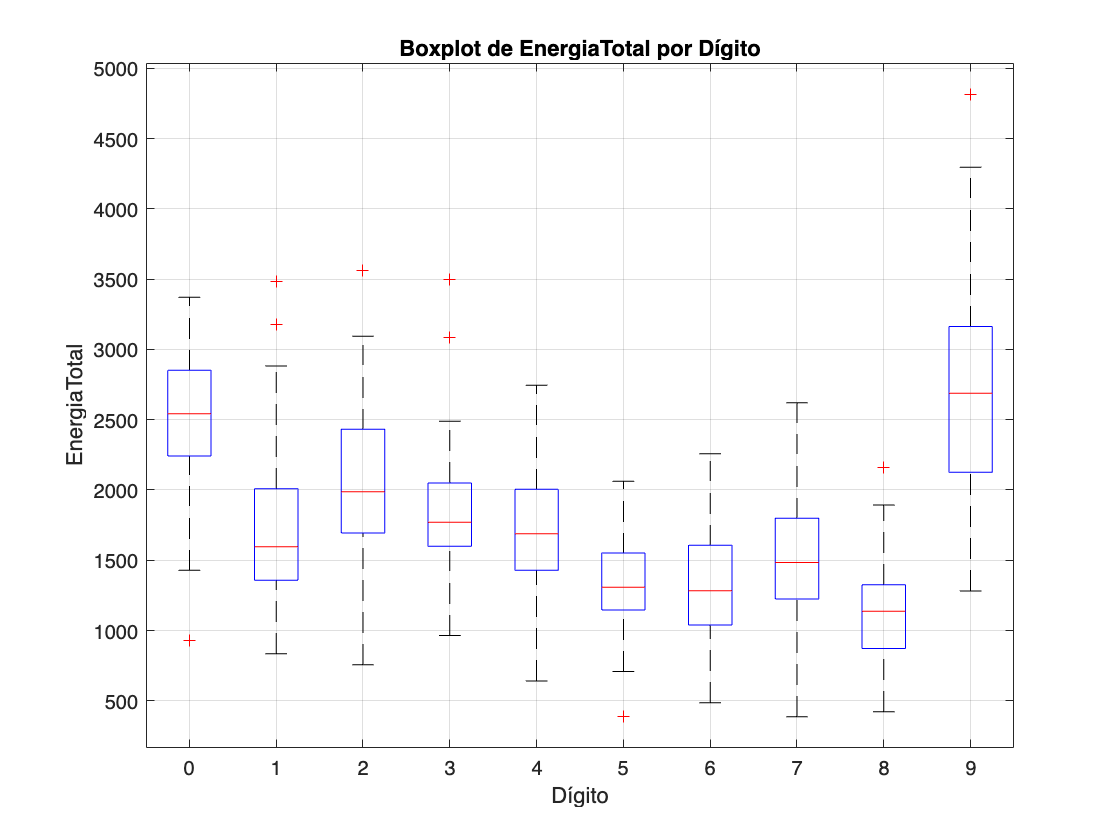

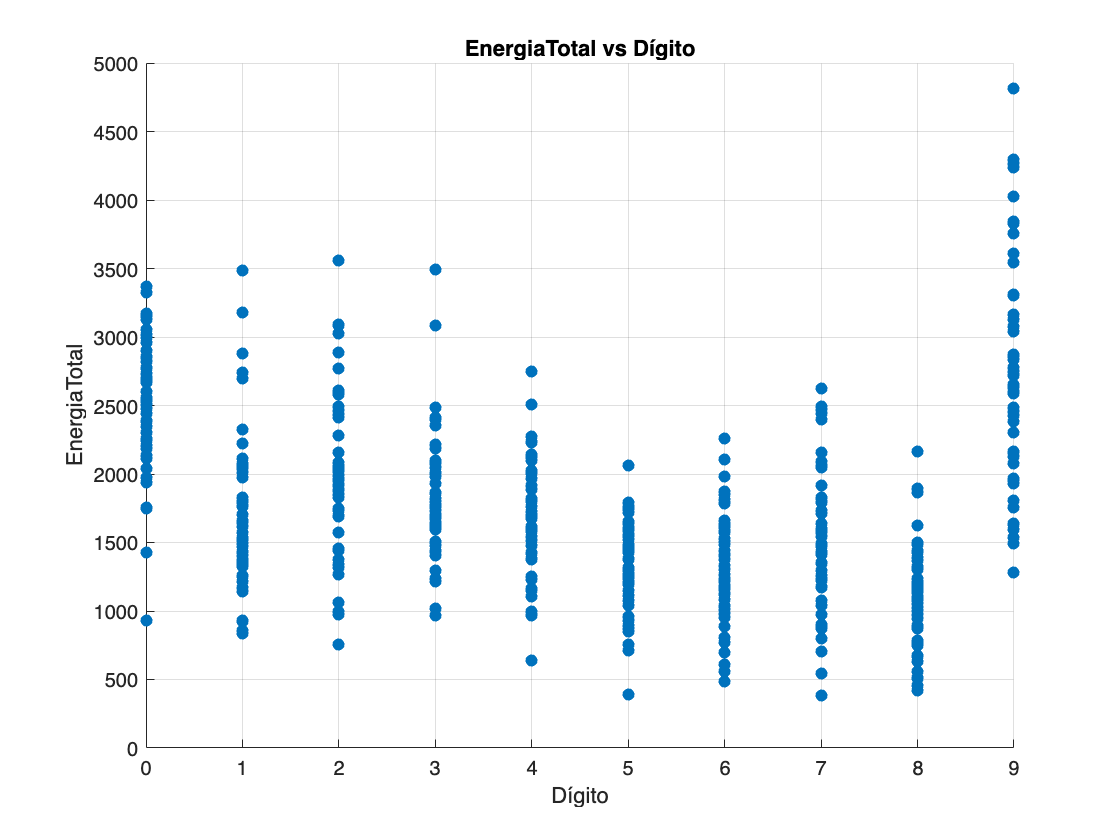

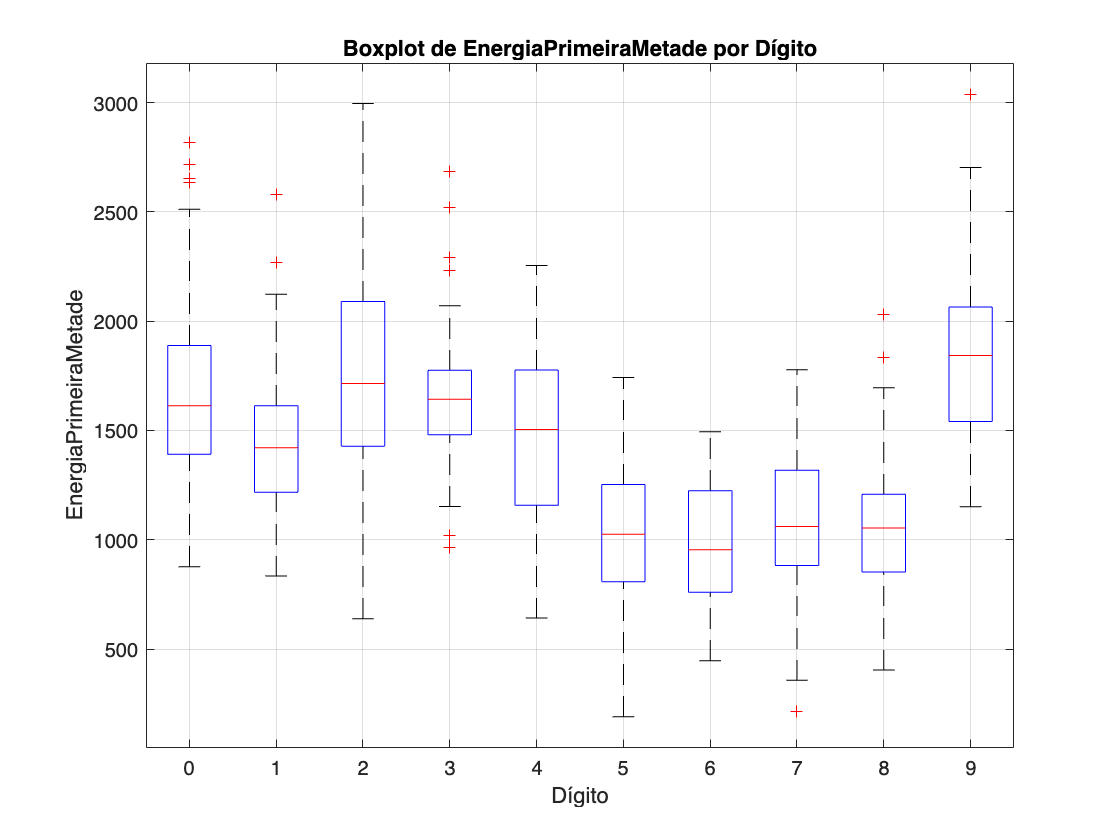

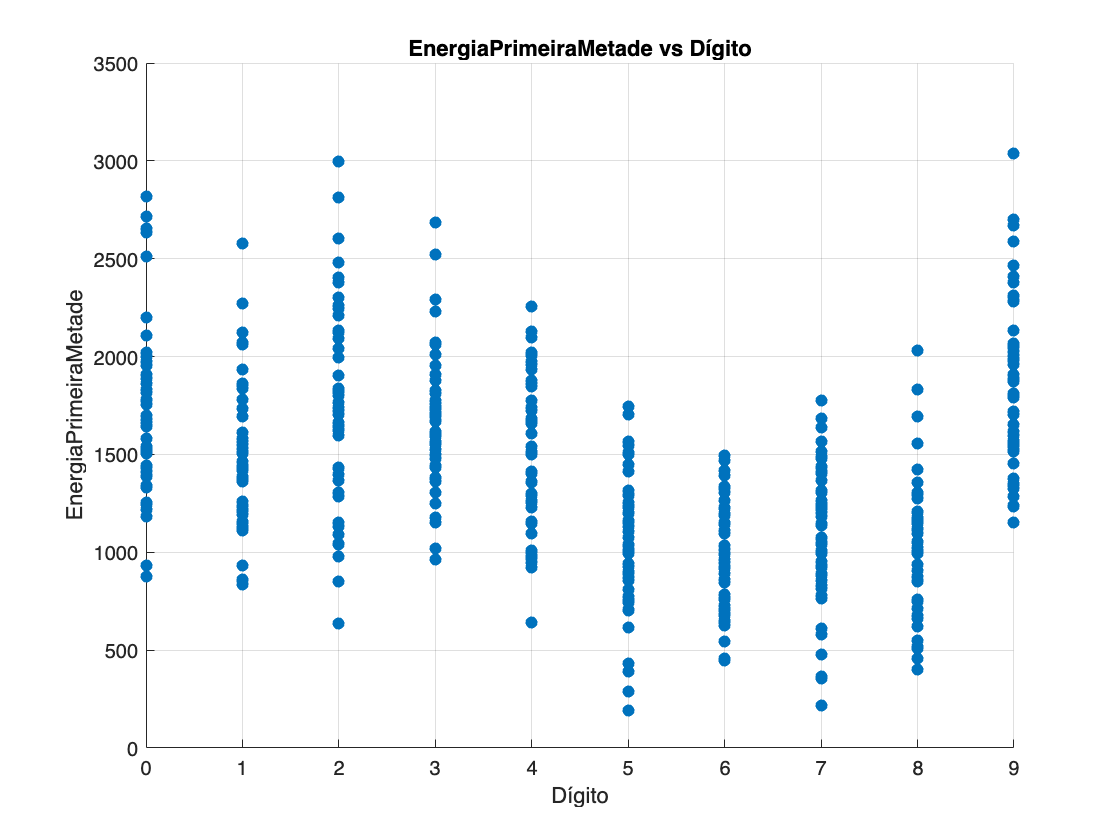

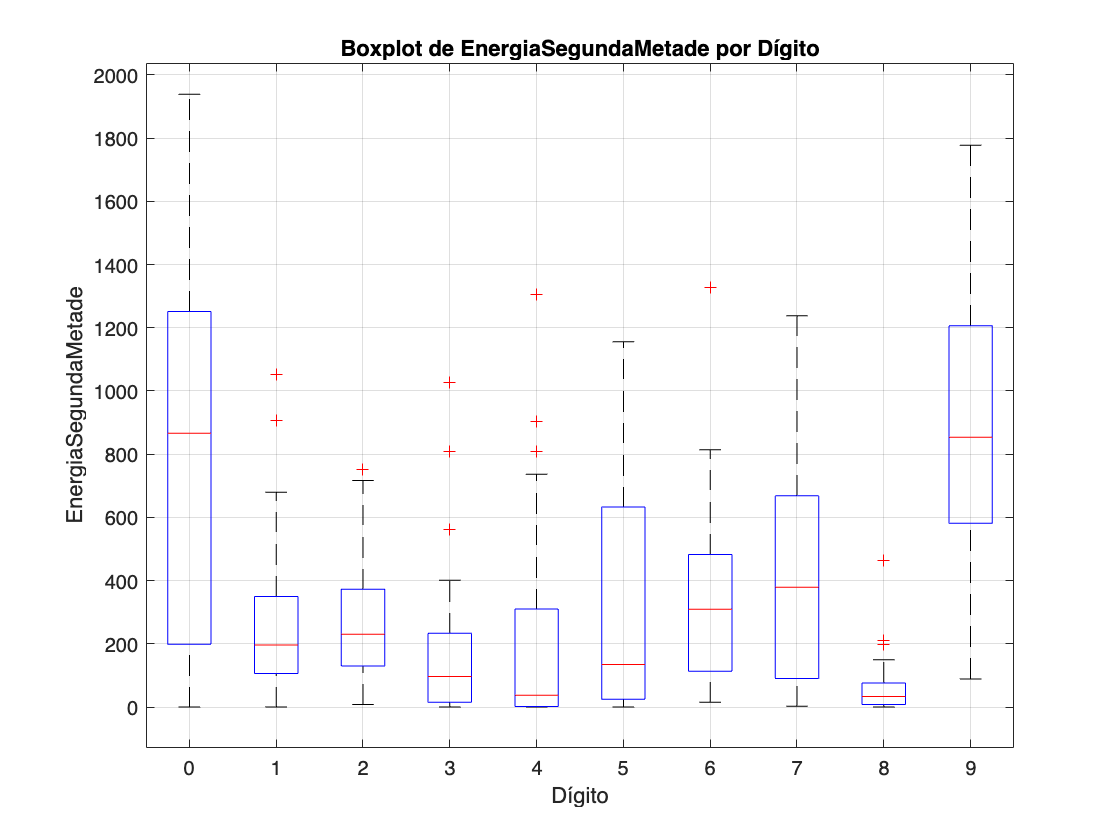

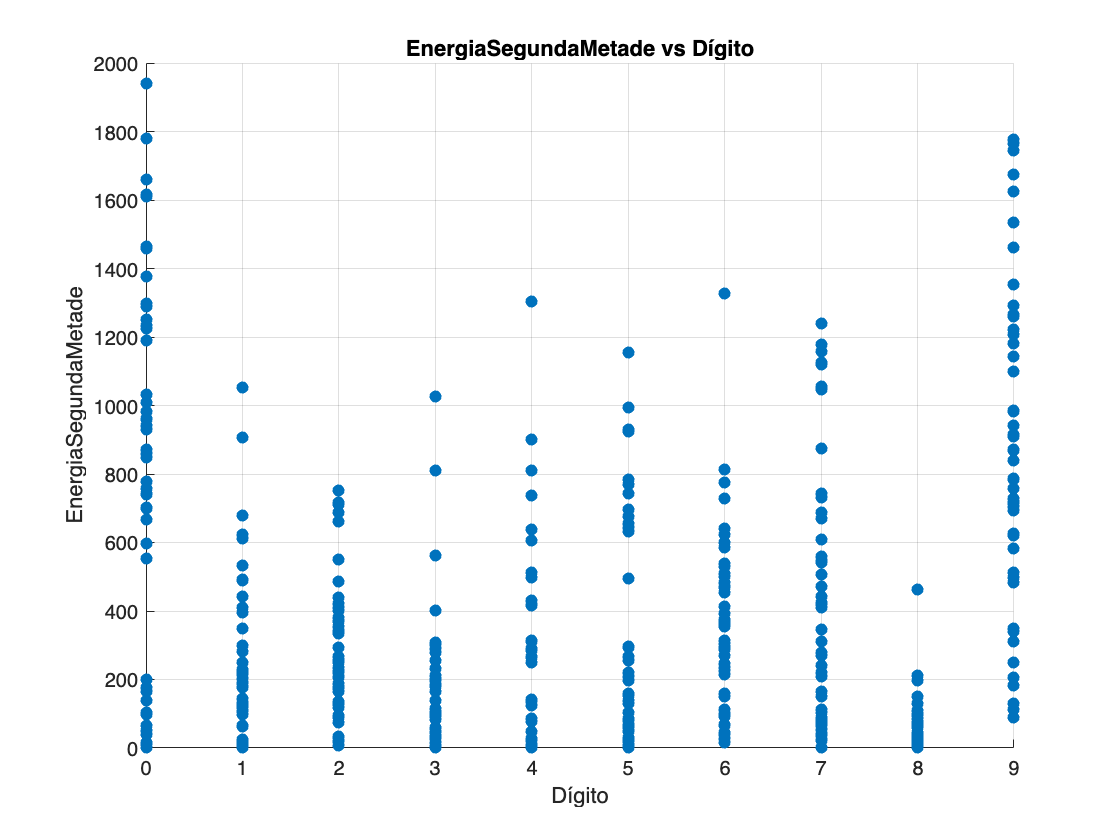

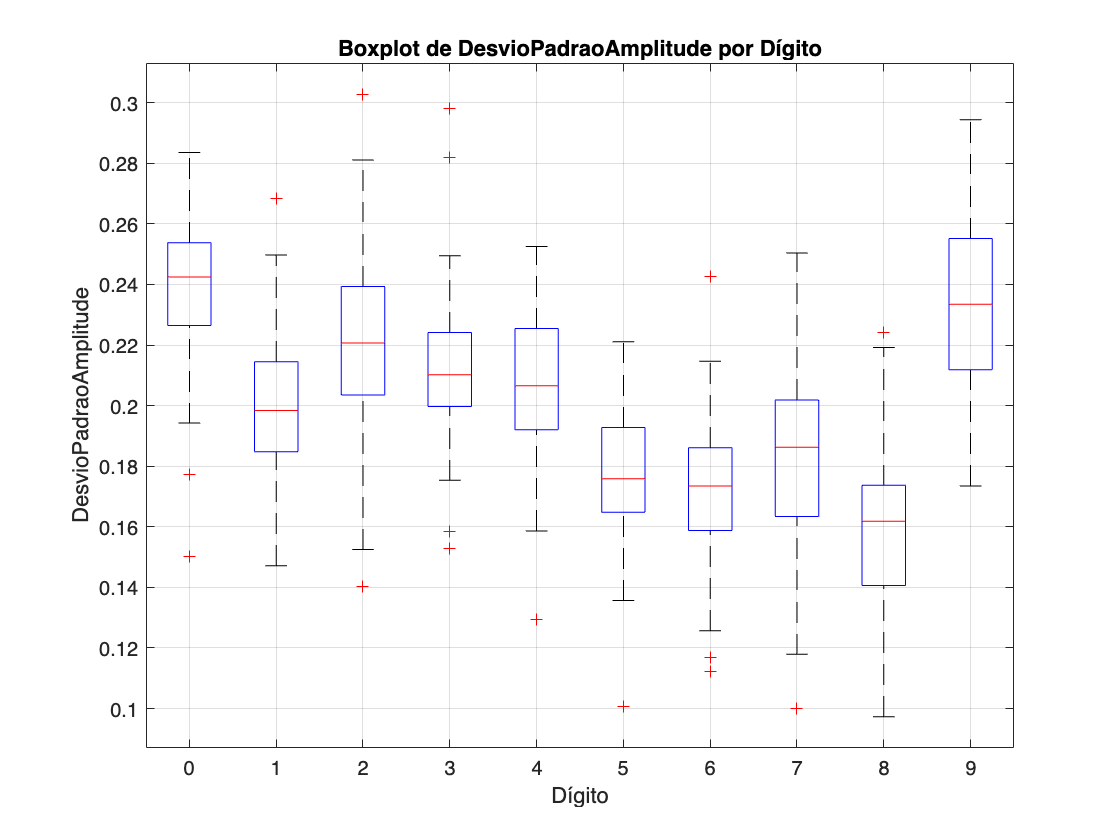

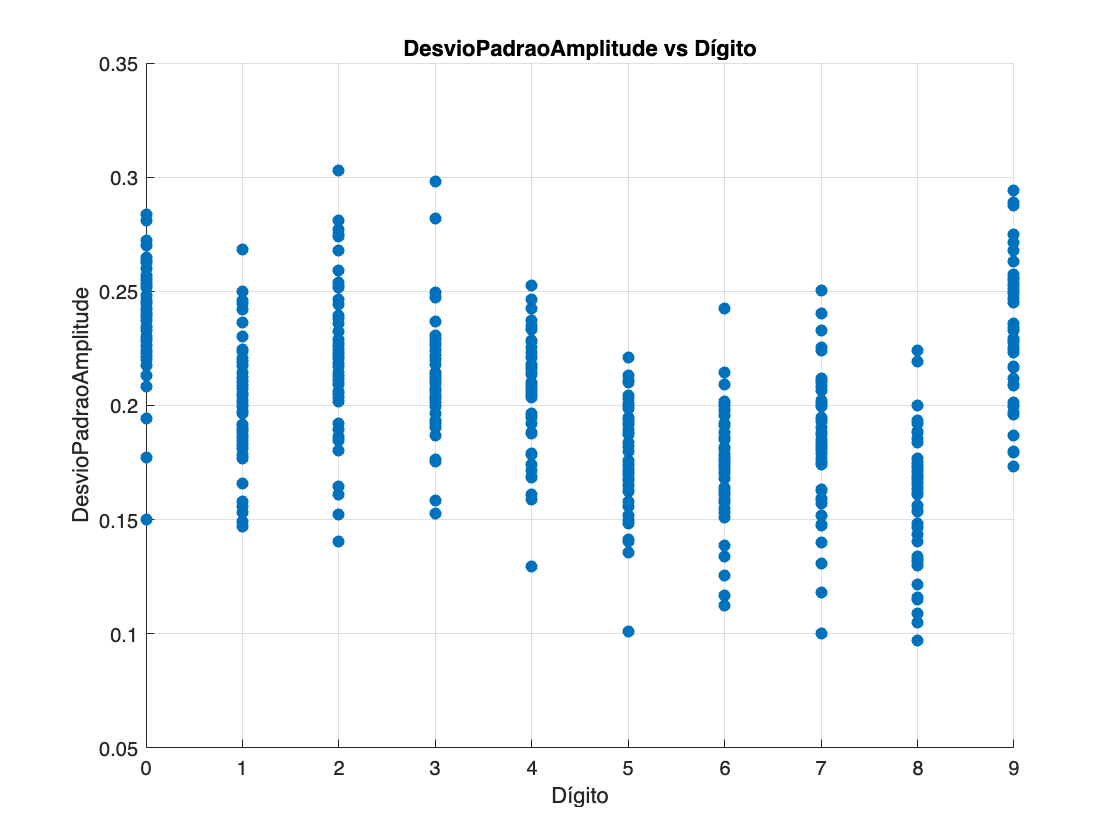

% Lista de características calculadas para a criação dos gráficos
features = {'EnergiaTotal','EnergiaPrimeiraMetade','EnergiaSegundaMetade',...
    'DesvioPadraoAmplitude','RMS','MediaAmplitude','FatorCrest','TaxaCruzamento'};

% Loop para criar gráficos (boxplot e dispersão 2D) para cada característica
for i = 1:length(features)
    feat = features{i};
    
    % Cria um boxplot da característica em função do dígito
    figure('Name', sprintf('Boxplot - %s por Dígito', feat), 'NumberTitle', 'off');
    boxplot(tabelaFinal.(feat), tabelaFinal.Digito);
    xlabel('Dígito');
    ylabel(feat);
    title(sprintf('Boxplot de %s por Dígito', feat));
    grid on;
    
    % Cria um gráfico de dispersão 2D da característica versus dígito
    figure('Name', sprintf('Dispersão 2D - %s por Dígito', feat), 'NumberTitle', 'off');
    scatter(tabelaFinal.Digito, tabelaFinal.(feat), 'filled');
    xlabel('Dígito');
    ylabel(feat);
    title(sprintf('%s vs Dígito', feat));
    grid on;
end

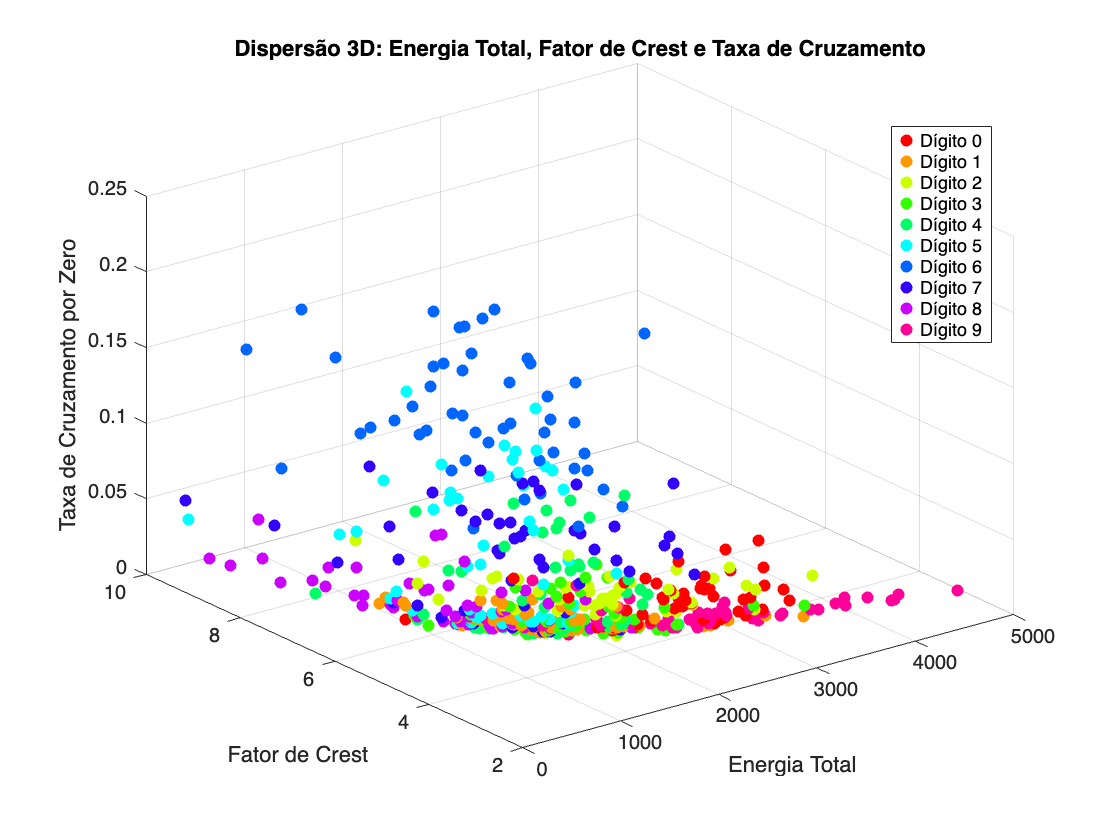

% Gráfico 3D para visualizar a relação entre três características selecionadas:
% - Energia Total, Fator de Crest e Taxa de Cruzamento por Zero

% Mapeia os dígitos para cores distintas
digitosUnicos = unique(tabelaFinal.Digito);
numDigitos = numel(digitosUnicos);
cores = hsv(numDigitos);  % Cada linha representa uma cor

% Cria um array de cores para cada ponto, de acordo com o dígito
coresPontos = zeros(height(tabelaFinal), 3);
for i = 1:height(tabelaFinal)
    idx = find(digitosUnicos == tabelaFinal.Digito(i));
    coresPontos(i,:) = cores(idx,:);
end

% Cria o gráfico 3D usando scatter3 com pontos coloridos
figure('Name','Dispersão 3D - Características Selecionadas','NumberTitle','off');
scatter3(tabelaFinal.EnergiaTotal, tabelaFinal.FatorCrest, tabelaFinal.TaxaCruzamento, 36, coresPontos, 'filled');
xlabel('Energia Total');
ylabel('Fator de Crest');
zlabel('Taxa de Cruzamento por Zero');
title('Dispersão 3D: Energia Total, Fator de Crest e Taxa de Cruzamento');
grid on;

% Cria handles fictícios para a legenda, associando cada dígito à sua cor
hold on;
dummyHandles = gobjects(numDigitos, 1);
for i = 1:numDigitos
    dummyHandles(i) = scatter3(NaN, NaN, NaN, 36, cores(i,:), 'filled');
end
hold off;

% Cria entradas na legenda com o dígito correspondente
entradasLegenda = arrayfun(@(d) sprintf('Dígito %d', d), digitosUnicos, 'UniformOutput', false);
legend(dummyHandles, entradasLegenda, 'Location', 'best');

## 9: Guardar a tabela final num arquivo MAT

save('AED1.mat', 'tabelaFinal');